# Atividade 4

% Read CSV data as table and Rename it
data = readtable("data/Data04.csv");
data.Properties.VariableNames = {'Amostra', 'Temp', 'Tensão mV'};

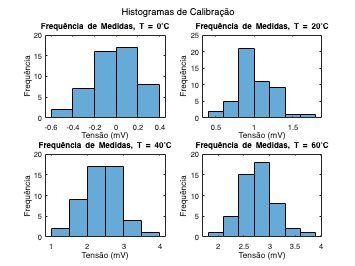

% Plot the histogram
h0 = data.("Tensão mV")(data.Temp == 0);
h1 = data.("Tensão mV")(data.Temp == 20);
h2 = data.("Tensão mV")(data.Temp == 40);
h3 = data.("Tensão mV")(data.Temp == 60);

subplot(2, 2, 1);
histogram(h0)
title('Frequência de Medidas, T = 0^{\circ}C')
ylabel('Frequência'), xlabel('Tensão (mV)');

subplot(2, 2, 2);
histogram(h1)
title('Frequência de Medidas, T = 20^{\circ}C')
ylabel('Frequência'), xlabel('Tensão (mV)');

subplot(2, 2, 3);
histogram(h2)
title('Frequência de Medidas, T = 40^{\circ}C')
ylabel('Frequência'), xlabel('Tensão (mV)');

subplot(2, 2, 4);
histogram(h3)
title('Frequência de Medidas, T = 60^{\circ}C')
ylabel('Frequência'), xlabel('Tensão (mV)');

sgtitle('Histogramas de Calibração');

alpha = .95 + (.05/2)

alpha = 0.9750

t_student = tinv(alpha, 49)

t_student = 2.0096


h0_m = mean(h0)

h0_m = -0.0116

h0_conf_inter = t_student .* (std(h0) ./ sqrt(50))

h0_conf_inter = 0.0560


h1_m = mean(h1)

h1_m = 1.0094

h1_conf_inter = t_student .* (std(h1) ./ sqrt(50))

h1_conf_inter = 0.0692


h2_m = mean(h2)

h2_m = 2.4178

h2_conf_inter = t_student .* (std(h2) ./ sqrt(50))

h2_conf_inter = 0.1400


h3_m = mean(h3)

h3_m = 2.7708

h3_conf_inter = t_student .* (std(h3) ./ sqrt(50))

h3_conf_inter = 0.0922

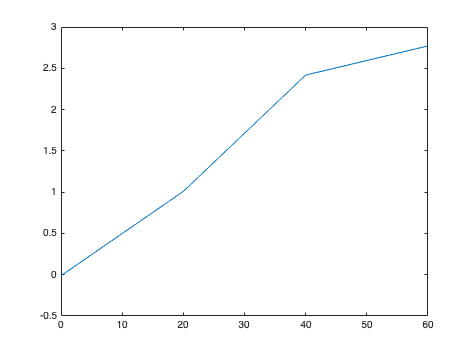

clf;
temp = [0 20 40 60]';
medias =  [h0_m h1_m h2_m h3_m]';

plot(temp,medias)

f = fit(temp, medias, 'poly2')

f =      Linear model Poly2:
     f(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =  -0.0004175  (-0.005541, 0.004706)
       p2 =     0.07383  (-0.247, 0.3946)
       p3 =     -0.0837  (-4.079, 3.911)

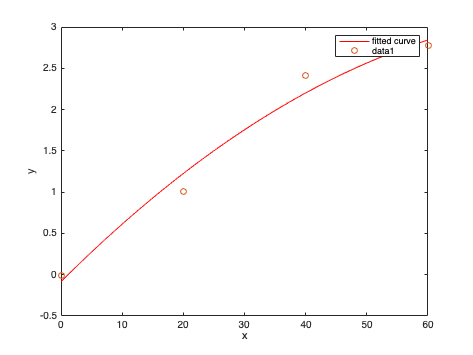

plot(f)
hold on 
scatter(temp, medias)